% m_\phi^2 vs. R_0, varying \beta, keeping \alpha = 0.05

% Parameters
R_c = 1;  % Given in the problem
alpha = 0.05;  % Keep alpha fixed at 0.05
beta_vals = [0.15, 0.20, 0.25];  % Vary beta values
R_0_range = linspace(0.01, 2.5, 100);  % Range of R_0 to plot (0 to 2.5)

% Pre-allocate array for m_phi squared results
m_phi_squared_beta = zeros(length(beta_vals), length(R_0_range));

% Calculate m_\phi^2 for different beta values
for i = 1:length(beta_vals)
    beta = beta_vals(i);
    % Calculate m_\phi^2 based on the given formula
    m_phi_squared_beta(i, :) = (R_c .* exp(R_0_range / R_c) .* ...
        (pi * (R_0_range.^4 + R_c^4).^2 - 8 * alpha * R_0_range.^5 * R_c^3) - ...
        pi * beta * (R_0_range + R_c) .* (R_0_range.^4 + R_c^4).^2) ./ ...
        (3 * pi * beta * (R_0_range.^4 + R_c^4).^2 - 6 * alpha * R_c^4 .* exp(R_0_range / R_c) .* (R_c^4 - 3 * R_0_range.^4));
end

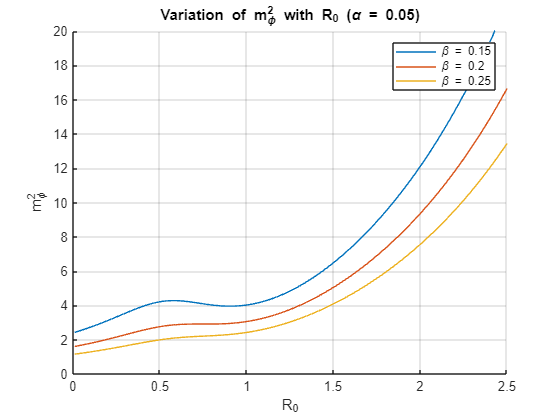

% Plot the second graph
figure;
hold on;
for i = 1:length(beta_vals)
    plot(R_0_range, m_phi_squared_beta(i, :), 'DisplayName', ['\beta = ', num2str(beta_vals(i))]);
end
xlabel('R_0');
ylabel('m_\phi^2');
title('Variation of m_\phi^2 with R_0 (\alpha = 0.05)');
legend('show');
grid on;
axis([0 2.5 0 20]); % Set the x and y axis limits
hold off;